load sunspot.dat
yr = sunspot(:,1);
sunspotNumber = sunspot(:,2);

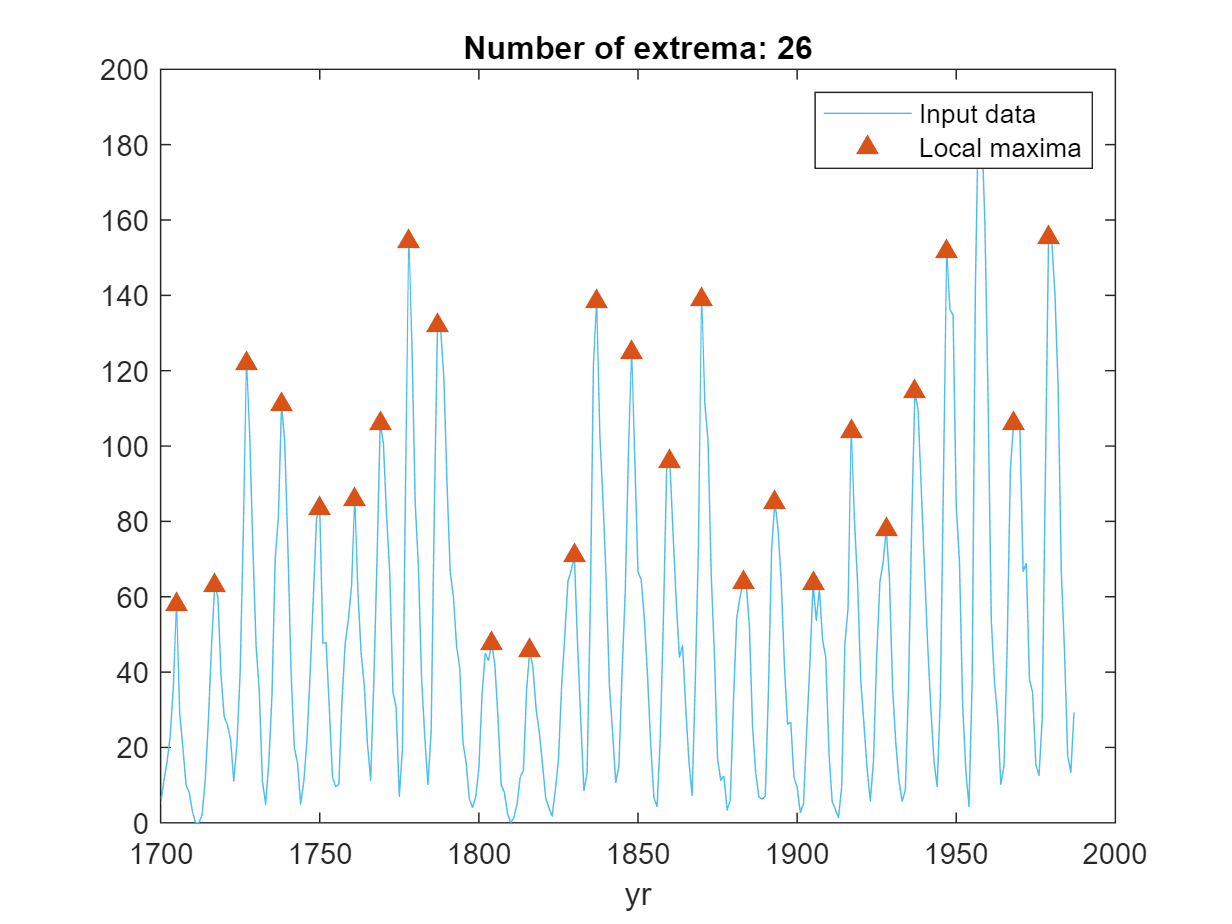

% Find local maxima
maxIndices = islocalmax(sunspotNumber,"MinSeparation",7,"SamplePoints",yr);

% Display results
clf
plot(yr,sunspotNumber,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(yr(maxIndices),sunspotNumber(maxIndices),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices))
hold off
legend
xlabel("yr")

mean(diff(yr(maxIndices)))

ans = 10.9600

SampRate = 50;
AccRetimed = retime(Acceleration,"regular","linear",TimeStep=seconds(1/SampRate));
jogSignal = detrend(AccRetimed.Y(AccRetimed.Timestamp > "14-Jul-2019 18:51:32"));
[pxx,w] = periodogram(jogSignal,[],[],SampRate)

pxx =     0.0000
    0.8410
    1.0068
    0.5451
    0.4597
    0.3760
    0.7829
    0.8523
    0.7777
    0.6927


w =          0
    0.0244
    0.0488
    0.0732
    0.0977
    0.1221
    0.1465
    0.1709
    0.1953
    0.2197


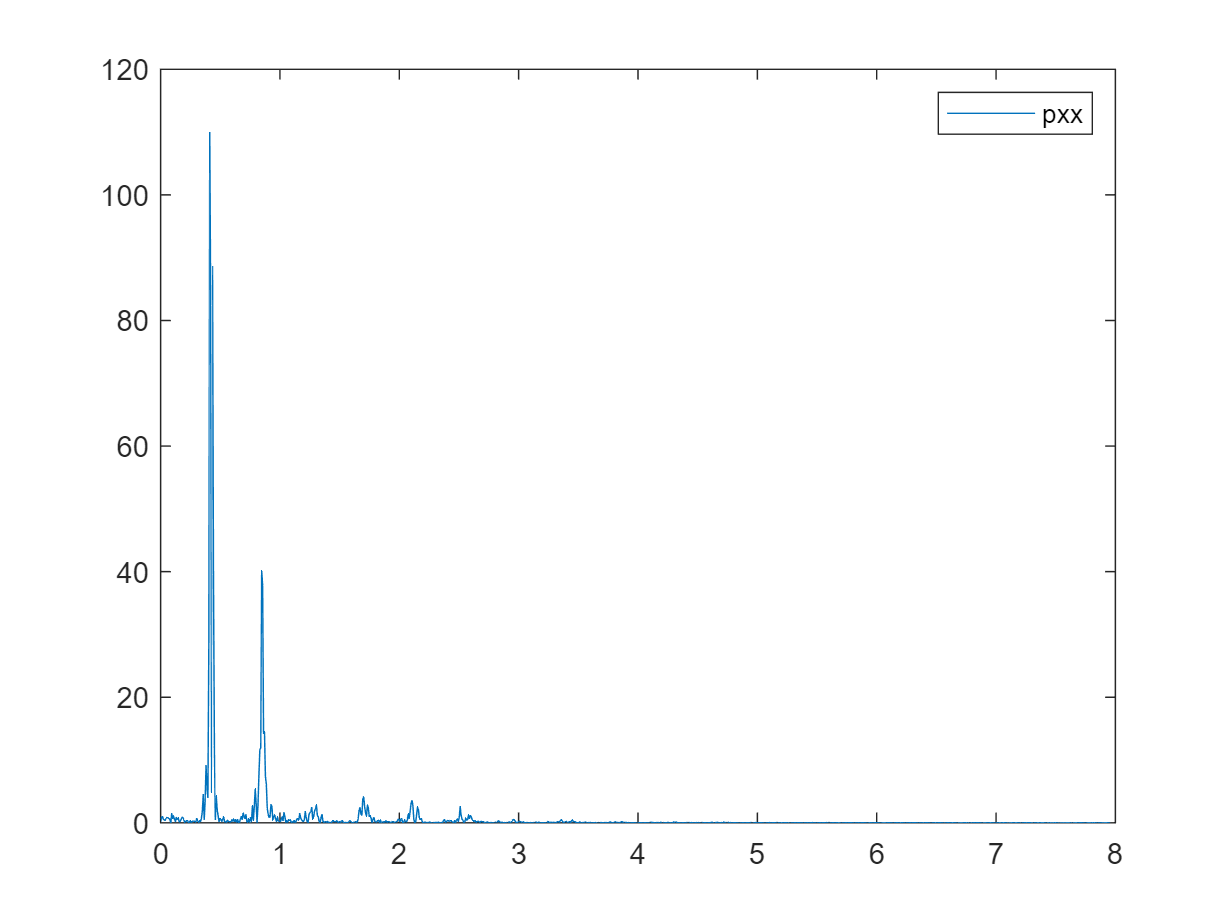

plot(w/pi,pxx)
legend('pxx')

% xlabel('\omega / \pi')

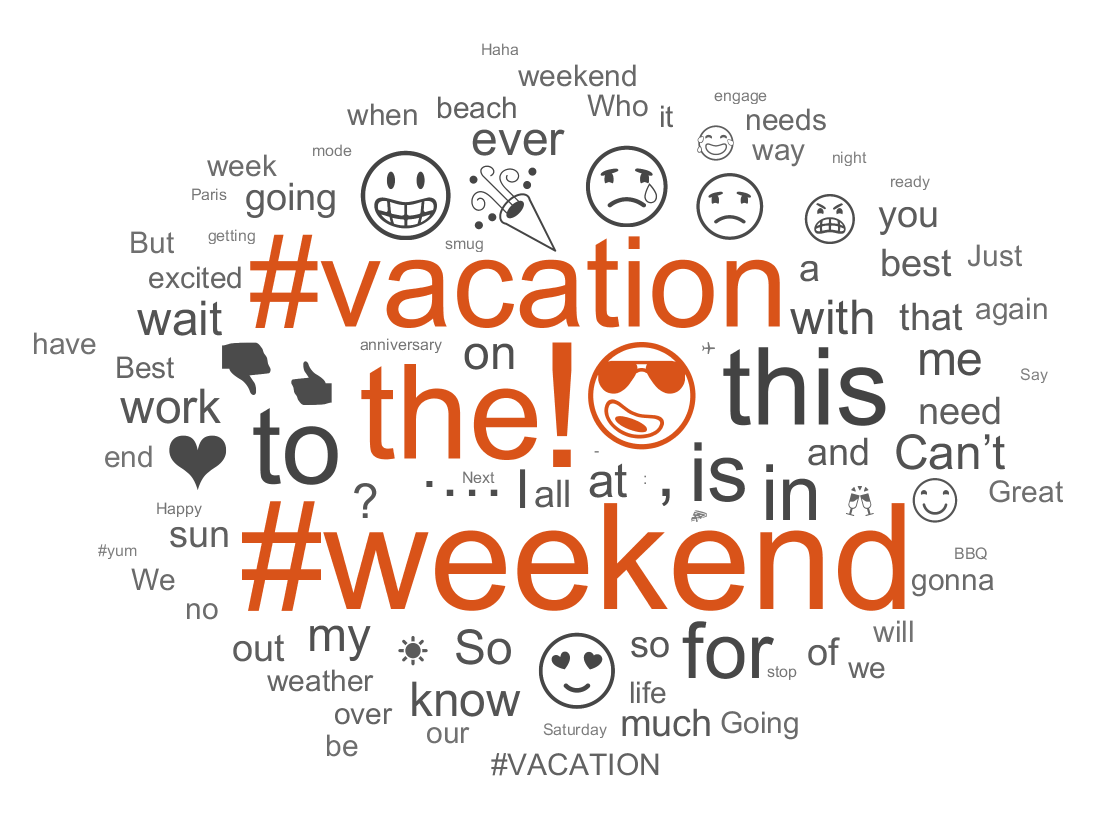

ans =   WordCloudChart with properties:

           WordData: ["!"    "#weekend"    "the"    "#vacation"    "😎"    "this"    "to"    "😀"    "🎉"    "😢"    "😍"    "is"    "for"    "in"    "❤"    ","    "☹"    "👎"    "…"    "👍"    "."    "I"    "😠"    "on"    "with"    "me"    …    ]
           SizeData: [38 28 23 21 18 16 16 13 11 11 10 10 9 9 8 8 8 8 7 6 6 5 5 4 4 4 4 4 4 4 4 4 4 4 4 4 3 3 3 3 3 3 3 3 3 3 3 3 3 3 3 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 2 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 … ]
    MaxDisplayWords: 100

  Show all properties


tbl = readtable("weekendUpdates.xlsx", "TextType", "string"); textData = tbl.TextData; 
tokenizedTextData = tokenizedDocument(textData);

wordcloud(tokenizedTextData)

tokenizedTextData = erasePunctuation(tokenizedTextData);
tokenizedTextData = removeStopWords(tokenizedTextData);
tokenizedTextData = lower(tokenizedTextData);

bagTextData = bagOfWords(tokenizedTextData);
top5Tokens = topkwords(bagTextData,5)

top5Tokens = 5×2 table
       Word        Count
    ___________    _____

    "#weekend"      28  
    "#vacation"     23  
    "😎"            18  
    "😀"            13  
    "🎉"            11  


sunglassesEmoji = "😎";
extractedEmojiInTable = ismember(tokenizedTextData.tokenDetails.Token,sunglassesEmoji);
numOfPostWithEmojis = length(unique(tokenizedTextData.tokenDetails.DocumentNumber(extractedEmojiInTable)));
perOfDocumentsWithSunglassesEmoji = numOfPostWithEmojis/length(textData)

perOfDocumentsWithSunglassesEmoji = 0.2800